# Potentiometric Surface Calculation

## Basic Version - constant density

cd 'G:\My Drive\PhD_Research\BSF_Thesis\ModernAndSurfaceProcesses\Analyses\ModProcAnalyses\Groundwater'
cd EquivalentHeadCalculation\data\input\

load('BrineDensity.mat')
load('BSFWellDatabase.mat')
load('Bflat30min.mat')

load('BLM41_complete.mat')
load('BLM43A_complete.mat')
load('BLM45_complete.mat')
load('BLM50B_complete.mat')
load('BLM53_complete.mat')
load('BLM53B_complete.mat')
load('BLM63_complete.mat')
load('BLM64_complete.mat')
load('BLM93_complete.mat')
load('BLM93A_complete.mat')
load('BLM93C_complete.mat')
load('BLM12_complete.mat')
load('BLM16_complete.mat')
load('BLM16A_complete.mat')
load('BLM31_complete.mat')
load('BLM34_complete.mat')
load('BLM37_complete.mat')

BLM12 = sortrows(BLM12,'Date_Time_MDT','ascend');

rhoHalite = 1211.1; %(kg/m3) %Reference density - mean halite saturated density using BLM93C equation and 10 cm soil temp as input

### BLM93C

DensitySubset = BrineDensity(BrineDensity.WellID == "BLM-93C", :);
rhoSample = mean(DensitySubset.FieldDensitygcm*1000) %(kg/m3)

rhoSample = 1.2087e+03

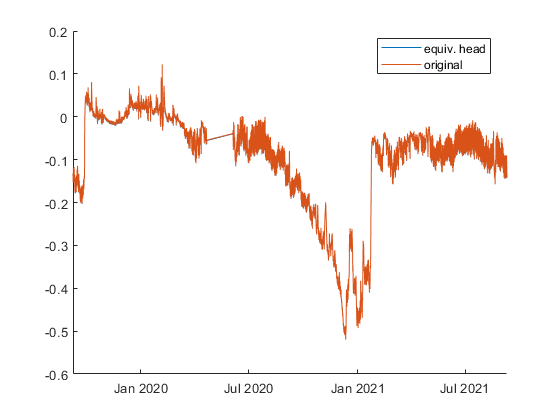

BLM93C  = EquivHead(BLM93C, 311, BSFWellDatabase, rhoSample, rhoHalite); %Function to do equivalent head calculation

### BLM93

%Add in manual measurements
BLM93.Properties.RowTimes(103562) = '7/25/21 07:15:00 PM';
BLM93.Properties.RowTimes(103563) = '09/09/21 07:30:00 PM';
BLM93.WaterLevelBelowSurface_m(103562) = -0.039;
BLM93.WaterLevelBelowSurface_m(103563) = .04;

DensitySubset = BrineDensity(BrineDensity.WellID == "BLM-93", :);
rhoSample = mean(DensitySubset.FieldDensitygcm*1000) %(kg/m3)

rhoSample = 1.1881e+03

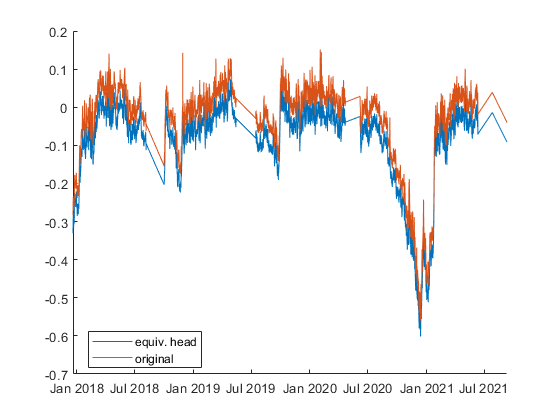

BLM93  = EquivHead(BLM93, 308, BSFWellDatabase, rhoSample, rhoHalite); %Function to do equivalent head calculation

### BLM93A

DensitySubset = BrineDensity(BrineDensity.WellID == "BLM-93A", :);
rhoSample = mean(DensitySubset.FieldDensitygcm*1000) %(kg/m3)

rhoSample = 1.1252e+03

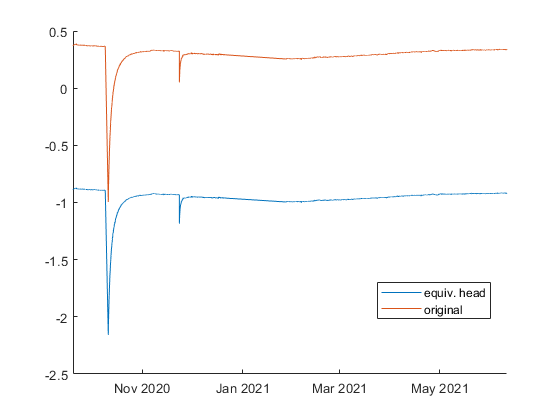

BLM93A  = EquivHead(BLM93A, 309, BSFWellDatabase, rhoSample, rhoHalite); %Function to do equivalent head calculation

### BLM64

DensitySubset = BrineDensity(BrineDensity.WellID == "BLM-64", :);
rhoSample = mean(DensitySubset.FieldDensitygcm*1000) %(kg/m3)

rhoSample = 1.1937e+03

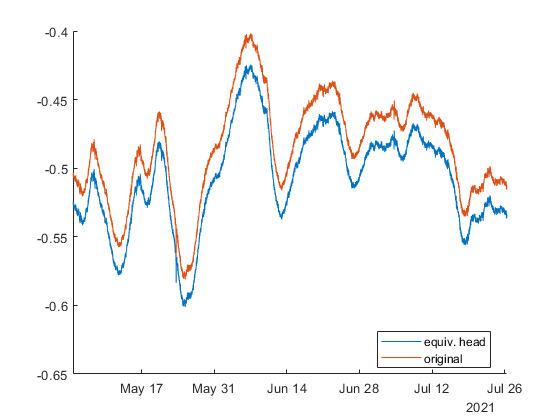

BLM64  = EquivHead(BLM64, 279, BSFWellDatabase, rhoSample, rhoHalite); 

### BLM63

DensitySubset = BrineDensity(BrineDensity.WellID == "BLM-63", :);
rhoSample = mean(DensitySubset.FieldDensitygcm*1000) %(kg/m3)

rhoSample = 1.1893e+03

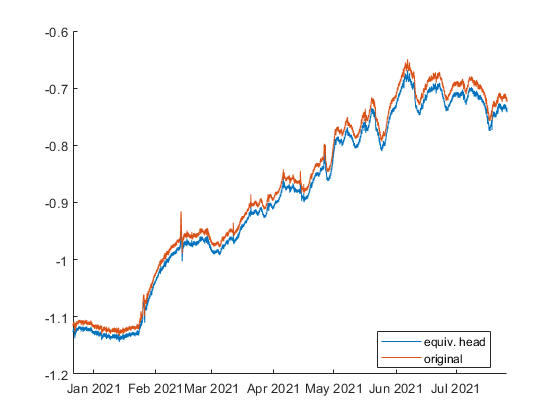

BLM63  = EquivHead(BLM63, 278, BSFWellDatabase, rhoSample, rhoHalite);

### BLM53

DensitySubset = BrineDensity(BrineDensity.WellID == "BLM-53", :);
rhoSample = mean(DensitySubset.FieldDensitygcm*1000) %(kg/m3)

rhoSample = 1.1938e+03

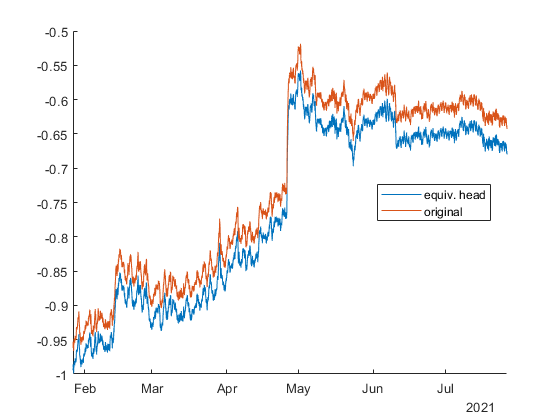

BLM53  = EquivHead(BLM53, 265, BSFWellDatabase, rhoSample, rhoHalite);

### BLM53B

DensitySubset = BrineDensity(BrineDensity.WellID == "BLM-53B", :);
rhoSample = mean(DensitySubset.FieldDensitygcm*1000) %(kg/m3)

rhoSample = 1.1942e+03

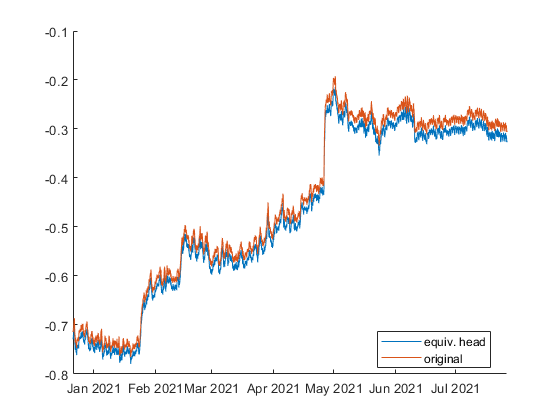

BLM53B  = EquivHead(BLM53B, 267, BSFWellDatabase, rhoSample, rhoHalite);

### BLM50B 

DensitySubset = BrineDensity(BrineDensity.WellID == "BLM-50B", :);
rhoSample = mean(DensitySubset.FieldDensitygcm*1000) %(kg/m3)

rhoSample = 1.1924e+03

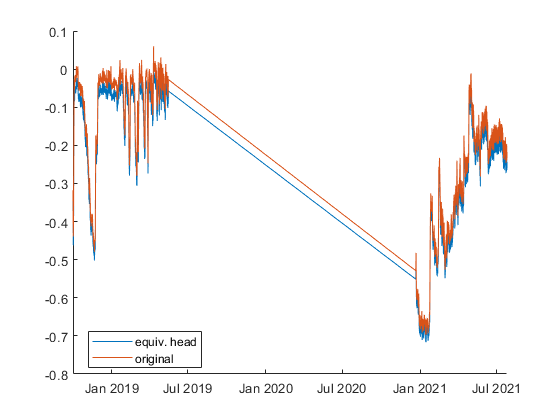

BLM50B  = EquivHead(BLM50B, 262, BSFWellDatabase, rhoSample, rhoHalite); %Function to do equivalent head calculation

### BLM45

DensitySubset = BrineDensity(BrineDensity.WellID == "BLM-45", :);
rhoSample = mean(DensitySubset.FieldDensitygcm*1000) %(kg/m3)

rhoSample = 1.1974e+03

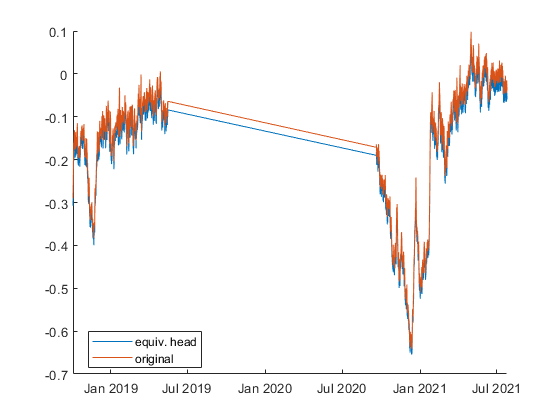

BLM45  = EquivHead(BLM45, 254, BSFWellDatabase, rhoSample, rhoHalite); %Function to do equivalent head calculation

### BLM43A

DensitySubset = BrineDensity(BrineDensity.WellID == "BLM-43A", :);
rhoSample = mean(DensitySubset.FieldDensitygcm*1000) %(kg/m3)

rhoSample = 1.2066e+03

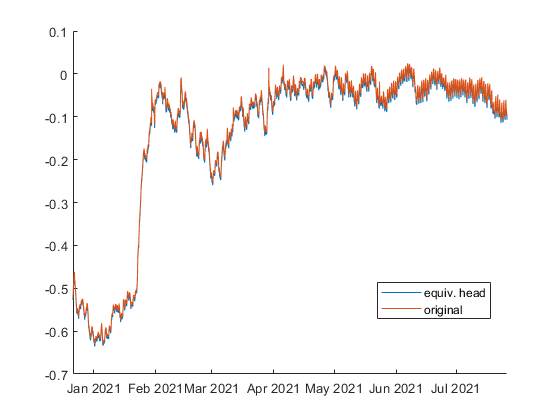

BLM43A  = EquivHead(BLM43A, 249, BSFWellDatabase, rhoSample, rhoHalite);

### BLM41

DensitySubset = BrineDensity(BrineDensity.WellID == "BLM-41", :);
rhoSample = mean(DensitySubset.FieldDensitygcm*1000) %(kg/m3)

rhoSample = 1.1929e+03

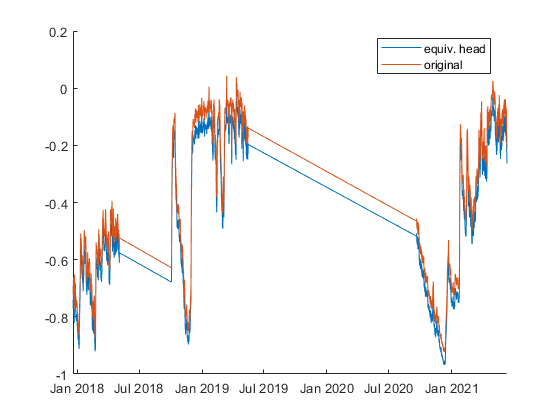

BLM41  = EquivHead(BLM41, 246, BSFWellDatabase, rhoSample, rhoHalite);

### BLM37

DensitySubset = BrineDensity(BrineDensity.WellID == "BLM-37", :);
rhoSample = mean(DensitySubset.FieldDensitygcm*1000) %(kg/m3)

rhoSample = 1.2003e+03

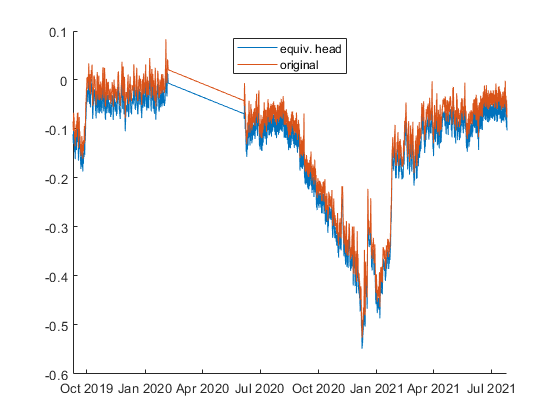

BLM37  = EquivHead(BLM37, 241, BSFWellDatabase, rhoSample, rhoHalite); %Function to do equivalent head calculation

### BLM34

DensitySubset = BrineDensity(BrineDensity.WellID == "BLM-34", :);
rhoSample = mean(DensitySubset.FieldDensitygcm*1000) %(kg/m3)

rhoSample = 1.1975e+03

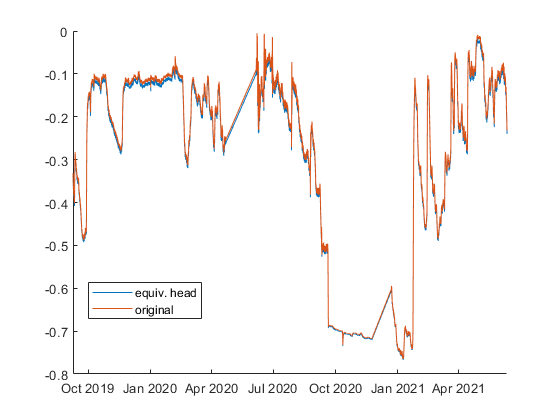

BLM34  = EquivHead(BLM34, 237, BSFWellDatabase, rhoSample, rhoHalite); %Function to do equivalent head calculation

### BLM31

DensitySubset = BrineDensity(BrineDensity.WellID == "BLM-31", :);
rhoSample = mean(DensitySubset.FieldDensitygcm*1000) %(kg/m3)

rhoSample = 1.1863e+03

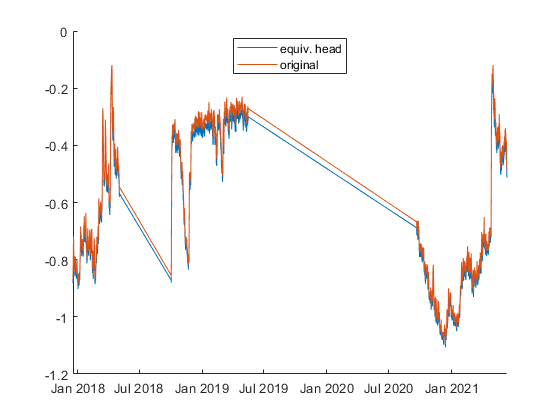

BLM31  = EquivHead(BLM31, 233, BSFWellDatabase, rhoSample, rhoHalite);

### BLM16A

DensitySubset = BrineDensity(BrineDensity.WellID == "BLM-16A", :);
rhoSample = mean(DensitySubset.FieldDensitygcm*1000) %(kg/m3)

rhoSample = 1.1914e+03

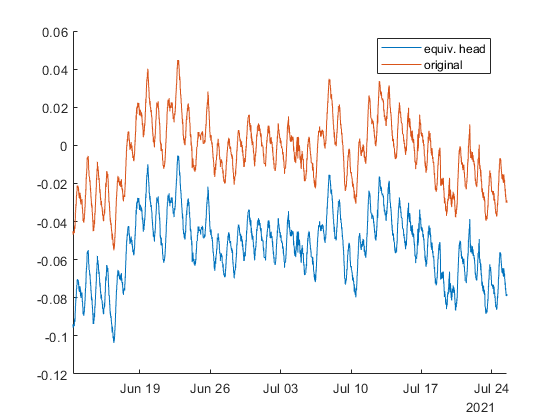

BLM16A  = EquivHead(BLM16A, 211, BSFWellDatabase, rhoSample, rhoHalite);

### BLM16

DensitySubset = BrineDensity(BrineDensity.WellID == "BLM-16", :);
rhoSample = mean(DensitySubset.FieldDensitygcm*1000) %(kg/m3)

rhoSample = 1.2080e+03

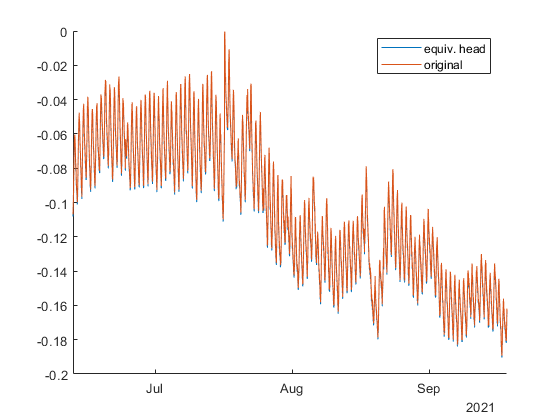

BLM16  = EquivHead(BLM16, 210, BSFWellDatabase, rhoSample, rhoHalite);

### BLM12

DensitySubset = BrineDensity(BrineDensity.WellID == "BLM-12", :);
rhoSample = mean(DensitySubset.FieldDensitygcm*1000) %(kg/m3)

rhoSample = 1.2025e+03

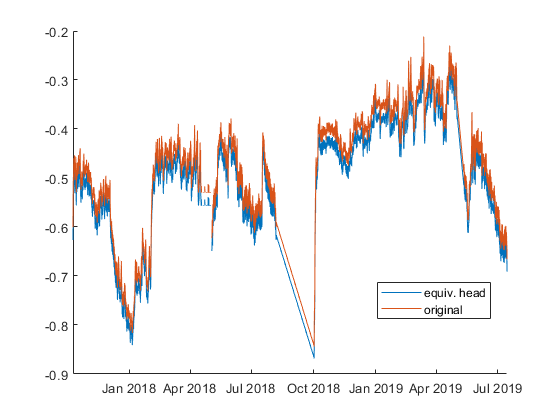

BLM12  = EquivHead(BLM12, 188, BSFWellDatabase, rhoSample, rhoHalite);

## Save Updated Well Data

cd ..\output\
save('BLM93A.mat', "BLM93A")
save('BLM93.mat', "BLM93")
save('BLM93C.mat', "BLM93C")
save('BLM64.mat', "BLM64")
save('BLM63.mat', "BLM63")
save('BLM53.mat', "BLM53")
save('BLM53B.mat', "BLM53B")
save('BLM50B.mat', "BLM50B")
save('BLM45.mat', "BLM45")
save('BLM43A.mat', "BLM43A")
save('BLM41.mat', "BLM41")
save('BLM37.mat', "BLM37")
save('BLM34.mat', "BLM34")
save('BLM31.mat', "BLM31")
save('BLM16.mat', "BLM16")
save('BLM16A.mat', "BLM16A")
save('BLM12.mat', "BLM12")

function [Well] = EquivHead(Well, WellRowNumber, BSFWellDatabase, rhoSample,rhoHalite)
%rhoHalite = 1211.1; %(kg/m3) %Reference density - mean halite saturated density using BLM93C equation and 10 cm soil temp as input

screenElevation = BSFWellDatabase.SurfaceElevation_m(WellRowNumber) - BSFWellDatabase.ScreenedInterval_midpoint_m(WellRowNumber);
headSample = BSFWellDatabase.SurfaceElevation_m(WellRowNumber) - (Well.WaterLevelBelowSurface_m);
Well.EquivalentHead_HaliteSaturated_BelowSurf_m = -((((rhoSample./rhoHalite).*headSample - ((rhoSample - rhoHalite)./rhoHalite).*screenElevation)) - BSFWellDatabase.SurfaceElevation_m(WellRowNumber)); 

figure
hold on
plot(Well.Date_Time_MDT, -Well.EquivalentHead_HaliteSaturated_BelowSurf_m, 'DisplayName','equiv. head')
plot(Well.Date_Time_MDT, -Well.WaterLevelBelowSurface_m, 'DisplayName','original')
xlim(Well.Date_Time_MDT([1,end]))
legend('location', 'best')
end